## Studio in frequenza del sistema a massa squilibrata 


$$\begin{cases}
\dot{q} = \omega\\
\ddot{q} = -\left(\frac{h_v}{J}\right)\cdot \omega  -  \left(\frac{ml g}J\right)\cdot q  +  \left(\frac{1}{J}\right)\cdot u
\end{cases}\\
\text{Passo dal dominio nel tempo allo spazio}\\
\ddot{q} = -\left(\frac{h_v}{J}\right)\cdot \omega  -  \left(\frac{ml g}J\right)\cdot cos(q)  +  \left(\frac{1}{J}\right)\cdot u \rightarrow^{t\rightarrow s} s^{2}q + \left(\frac{h_v}{J}\right)\cdot sq  +  \left(\frac{ml g}J\right)\cdot cos(q) = \left(\frac{1}{J}\right)\cdot u\\
\text{Considero  $\frac{mlg}{J}cos(q)$ come un disturbo sinusoidale introdotto dal sistema stesso }\\
G(s) = \frac{Q}{U} = \frac{\frac{1}{J}}{s^{2} + \left(\frac{h_v}{J}\right)\cdot s$$


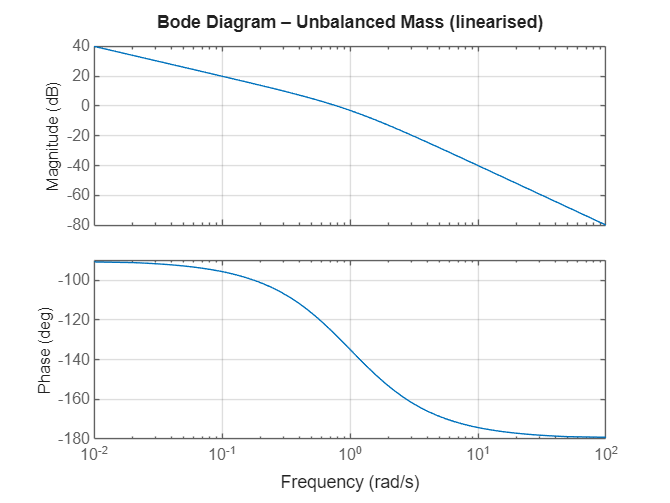

%% Parametri fisici
m  = 0.4;     % massa (kg)
hv = 1.0;     % attrito viscoso (N·m·s/rad)
J  = 1.0;     % inerzia rotazionale (kg·m²)
l  = 0.5;     % distanza del baricentro (m)
g  = 9.81;    % gravità (m/s²)

%% Funzione di trasferimento
num = [0 1/J];                      % (1/J)s
den = [1 hv/J 0];             % s² + (hv/J)s
G   = tf(num, den);

%% Diagramma di Bode
figure('Name','Bode – Unbalanced Mass');
bode(G);
grid on;
title('Bode Diagram – Unbalanced Mass (linearised)');


%% Opzionale: margini di stabilità
[Gm,Pm,Wcg,Wcp] = margin(G);
fprintf("Gain margin:  %.2f dB\nPhase margin: %.1f°\n", 20*log10(Gm), Pm);

Gain margin:  Inf dB
Phase margin: 51.8°


Definisco la fdt del LPF e del DELAY 

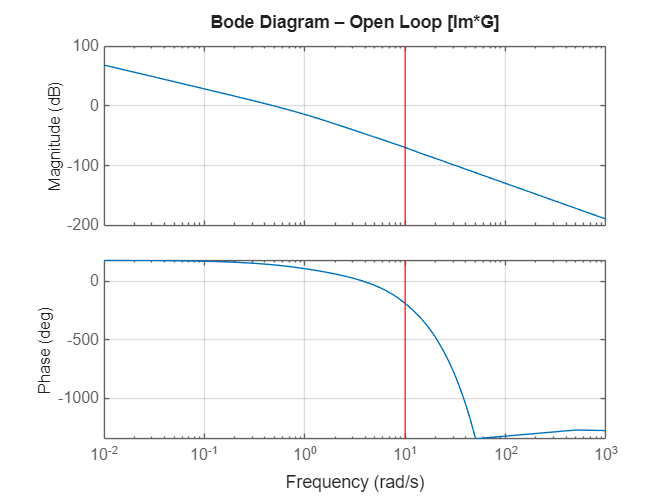

T = 3.15; %s
LPF = tf([0 1],[T 1]);

L = 0.5;
s = tf('s');
delay = exp(-L*s);

Im = feedback(LPF*delay, 1, +1); %Internal modified Model


%%Diagramma di Bode della catena aperta 
L = Im*G;
figure('Name','Bode – Open Loop');
bode(L);
grid on;
title('Bode Diagram – Open Loop [Im*G]');
ax = findall(gcf,'Type','axes');   % tutti gli assi nella figura
for k = 1:numel(ax)
    xline(ax(k), 10, 'r', 'LineWidth', 1);
end


gainW0 = abs(freqresp(L, 10))

gainW0 = 3.2571e-04

sistema retroazionato 

Gr = feedback(L, 1)


Gr =
 
  A = 
            x1       x2       x3
   x1        0        0      0.5
   x2  -0.6349       -1        0
   x3        0        1        0
 
  B = 
       u1
   x1   0
   x2   1
   x3   0
 
  C = 
           x1      x2      x3
   y1  0.6349       0       0
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.5 
 
Continuous-time state-space model.


dcgain(Gr)

ans = 1

[GM, PM, Wcg, Wcp] = margin(L)

GM = 2.7725e+03

PM = -39.6705

Wcg = 9.6636

Wcp = 0.4955